# **Inferenza e kriging**

## **Reset del workspace**

addpath ..\..\'D-STEM v2.1'\Src\
addpath ..\..\'D-STEM v2.1'\Src\fda\

clear all %#ok<CLALL> 
clc

## Importazione dei dati

data = load("..\Data\Processed data\Hourly_data.mat").hourly_data;
rho = 0;

### Cambio del nome delle variabili

data.Properties.VariableNames = ["Profile", "Y_name", "Y", "X_h_ora", "X_beta_cost", ...
    "X_beta_temp", "X_beta_pioggia", "X_beta_visib", "X_beta_vento", "X_beta_copert", ...
    "X_beta_dist", "X_beta_week", "X_beta_lockdown", "X_beta_euf", "X_beta_pop", "Y_coordinate", ...
    "X_coordinate", "Time"];

## Stima del modello fp-HDGM

### Costruzione dell'oggetto *stem_model*

#### Scelta del modello

o_modeltype = stem_modeltype('f-HDGM');
if rho ~= 0
    o_modeltype.flag_potential = true;
end

#### Creazione dell'oggetto *stem_fda*

input_fda.spline_type = 'Fourier';
input_fda.spline_range = [0 24];
input_fda.spline_nbasis_z = 7;
input_fda.spline_nbasis_beta = 5; 
input_fda.spline_nbasis_sigma = 5;
o_fda = stem_fda(input_fda);

#### Creazione dell'oggetto *stem_data*

input_data.stem_modeltype = o_modeltype;
input_data.data_table = data;
input_data.stem_fda = o_fda;
o_data = stem_data(input_data);

 
**********************************************
*   Data description of stem_varset object   *
**********************************************
Maximum number of observations per profile: q=24
 
Number of spatial locations: n=51
 
Number of time steps: T=366
 
Generating data matrices...
Generation ended.
Looking for duplicated sites...
Operation ended.


#### Creazione dell'oggetto *stem_model*

o_par = stem_par(o_data, 'exponential');
o_model = stem_model(o_data, o_par);

Generating data matrices...
Generation ended.


% o_model.stem_data.standardize;

#### Inizializzazione manuale dei parametri

if rho ~= 0
    o_par.rho = rho;
end
n_basis=o_fda.get_basis_number;
o_par.theta_z = ones(1,n_basis.z)*.01;
o_par.G = diag(ones(n_basis.z,1)*.5);
o_par.v_z = eye(n_basis.z)*.5;

#### Inizializzazione automatica dei parametri

if rho ~= 0
    T = size(o_model.stem_data.Y, 2);
    n = size(o_model.stem_data.stem_gridlist_p.grid{1, 1}.coordinate, 1);
    q = o_model.stem_par.q;
    o_model.set_distance_matrix
    Y = o_model.stem_data.Y;
    
    % depotenziamento dei dati originali
    diag_H_inv = stem_misc.compute_H_inv(o_model.DistMat_rho, ...
        q, o_par.rho);
    Y_pot = zeros(size(o_model.stem_data.Y));
    for t=1:T
        Y_pot(:, t) = diag_H_inv.*Y(:, t);
    end
    o_model.stem_data.stem_varset_p.Y = mat2cell(Y_pot, n.*ones(1, q));
    o_model.stem_data.Y = Y_pot;
end

o_par.beta = o_model.get_beta0();
o_par.sigma_eps = o_model.get_coe_log_sigma_eps0();
o_model.set_initial_values(o_par);

if rho ~= 0
    % ripristino dei dati originali
    o_model.stem_data.stem_varset_p.Y = mat2cell(Y, n.*ones(1, q));
    o_model.stem_data.Y = Y;
end

### Stima EM

#### Opzioni

o_EM_options = stem_EM_options();
o_EM_options.exit_tol_par = 0.0001;
o_EM_options.exit_tol_loglike = 0.0001;
o_EM_options.max_iterations = 50;

#### Avvio

o_model.EM_estimate(o_EM_options);

Generating point distance matrices...
Generation ended.
 
**********************
*   D-STEM version   *
**********************
 
Model estimation is performed using D-STEM v2
 
******************************
*   Brief data description   *
******************************
Number of variables: q=24
 
Point variables:
sum of points for each variable: Nq=1224
sum of sites for each variable: N=51
 
Date and time steps:
  Stating date  : 01-Jan-2020
  Ending date   : 31-Dec-2020
  Temporal steps: 366
 
Bounding box of the point data:
  Latitude min : 40.71 deg
  Latitude max : 40.75 deg
  Longitude min: -74.08 deg
  Longitude max: -74.03 deg
 
Number of latent variables: p=7
 
Covariates related to beta:
    {'cost'}    {'temp'}    {'pioggia'}    {'visib'}    {'vento'}    {'copert'}    {'dist'}    {'week'}    {'lockdown'}    {'euf'}    {'pop'}

************************
Iteration 1 started...
************************
  E step started...
    Kalman smoother started...
    Kalman smoother ended i

#### Impostazione della matrice di varianze e covarianze

flag_cov = true;
if flag_cov
    delta=0.001;
    o_model.set_varcov(delta);
    o_model.set_logL();
end

    Kalman filter started...
    Kalman filter ended in 5.62s
Derivatives allocation...
Derivatives initialization...
Hessian evaluation...
Hessian evaluation: 1% completed


Hessian evaluation: 2% completed


Hessian evaluation: 3% completed


Hessian evaluation: 4% completed


Hessian evaluation: 5% completed


Hessian evaluation: 6% completed


Hessian evaluation: 7% completed


Hessian evaluation: 8% completed


Hessian evaluation: 9% completed


Hessian evaluation: 10% completed


Hessian evaluation: 11% completed


Hessian evaluation: 12% completed


Hessian evaluation: 13% completed


Hessian evaluation: 14% completed


Hessian evaluation: 15% completed


Hessian evaluation: 16% completed


Hessian evaluation: 17% completed


Hessian evaluation: 18% completed


Hessian evaluation: 19% completed


Hessian evaluation: 20% completed


Hessian evaluation: 21% completed


Hessian evaluation: 22% completed


Hessian evaluation: 23% completed


Hessian evaluation: 24% completed


Hessian evaluation: 25% completed


Hessian evaluation: 26% completed


Hessian evaluation: 27% completed


Hessian evaluation: 28% completed


Hessian evaluation: 29% completed


Hessian evaluation: 30% completed


Hessian evaluation: 31% completed


Hessian evaluation: 32% completed


Hessian evaluation: 33% completed


Hessian evaluation: 34% completed


Hessian evaluation: 35% completed


Hessian evaluation: 36% completed


Hessian evaluation: 37% completed


Hessian evaluation: 38% completed
Hessian evaluation: 39% completed
Hessian evaluation: 40% completed
Hessian evaluation: 41% completed
Hessian evaluation: 42% completed
Hessian evaluation: 43% completed
Hessian evaluation: 44% completed
Hessian evaluation: 45% completed
Hessian evaluation: 46% completed
Hessian evaluation: 47% completed
Hessian evaluation: 48% completed
Hessian evaluation: 49% completed
Hessian evaluation: 50% completed
Hessian evaluation: 51% completed
Hessian evaluation: 52% completed
Hessian evaluation: 53% completed
Hessian evaluation: 54% completed
Hessian evaluation: 55% completed
Hessian evaluation: 56% completed
Hessian evaluation: 57% completed
Hessian evaluation: 58% completed
Hessian evaluation: 59% completed
Hessian evaluation: 60% completed
Hessian evaluation: 61% completed
Hessian evaluation: 62% completed
Hessian evaluation: 63% completed
Hessian evaluation: 64% completed
Hessian evaluation: 65% completed
Hessian evaluation: 66% completed
Hessian evalua

Log-Likelihood computation...
    Kalman smoother started...
    Kalman smoother ended in 13.18s
Log-Likelihood computation ended.


## Visualizzazione delle spline

****************
\Beta_(f) plot
****************
****************
Sigma(h) plot
****************


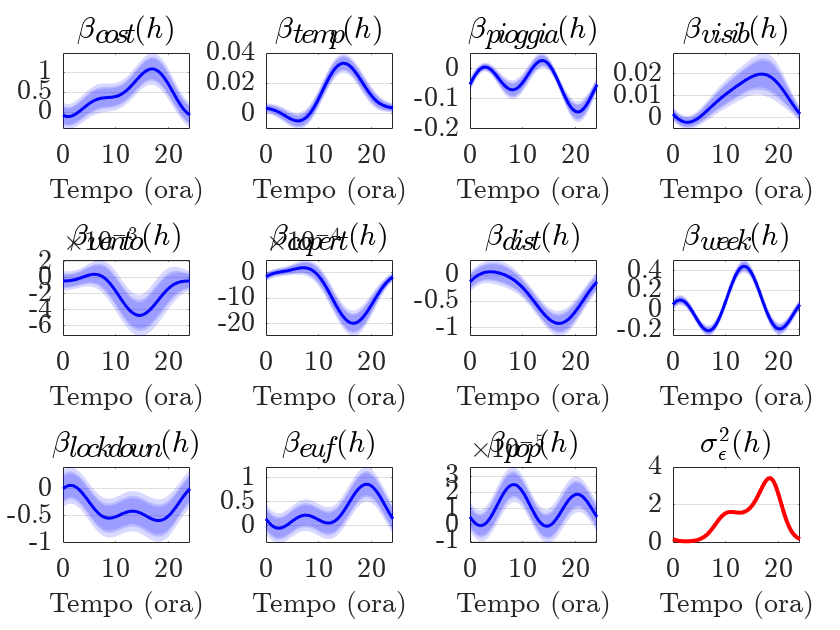

o_model.plot_par;

## Kriging

### Importazione dei confini ammistrativi di Jersey City

state_shape = shaperead("..\Data\Sources\Shape\Municipal_Boundaries_of_NJ.shp");
for i = 1:length(state_shape)
    if strcmp(state_shape(i).MUN, 'JERSEY CITY')
        city_shape = state_shape(i);
        break;
    end
end

### Conversione delle coordinate da WGS84 UTM32N a gradi

[city_shape.Y, city_shape.X] = projinv(shapeinfo("..\Data\Sources\Shape\Municipal_Boundaries_of_NJ.shp").CoordinateReferenceSystem, ...
    city_shape.X, city_shape.Y);
[city_shape.BoundingBox(:, 2), city_shape.BoundingBox(:, 1)] = projinv(shapeinfo("..\Data\Sources\Shape\Municipal_Boundaries_of_NJ.shp").CoordinateReferenceSystem, ...
    city_shape.BoundingBox(:, 1), city_shape.BoundingBox(:, 2));

### Costruzione della griglia

res = .0002;
lat = city_shape.BoundingBox(1, 2):res:city_shape.BoundingBox(2, 2);
lon = city_shape.BoundingBox(1, 1):res:city_shape.BoundingBox(2, 1);
[lon_mat, lat_mat] = meshgrid(lon,lat);
krig_coordinates = [lat_mat(:) lon_mat(:)];

o_krig_grid = stem_grid(krig_coordinates, 'deg', 'regular', ...
    'pixel', size(lat_mat), 'square', res, res);
o_krig_data = stem_krig_data(o_krig_grid);
o_model.stem_data.shape = city_shape;
o_krig = stem_krig(o_model, o_krig_data);

### Determinazione dei valori di $\mathbf{z}(\mathbf{s}, t)$ per ogni punto della griglia

o_krig_options = stem_krig_options();
o_krig_options.block_size = 30;
o_krig_options.back_transform = 0;
o_krig_options.no_varcov = 0;
o_krig_result = o_krig.kriging(o_krig_options);

Kriging started...
Kriging block 1 of 7669
Generating data matrices...
Generation ended.
Generating point distance matrices...
Generation ended.
    Kalman smoother started...
    Kalman smoother ended in 15.63s
Generating data matrices...
Generation ended.
Generating point distance matrices...
Generation ended.
Kriging block ended in 21.91s
Kriging block 2 of 7669
Generating data matrices...
Generation ended.
Generating point distance matrices...
Generation ended.
    Kalman smoother started...
    Kalman smoother ended in 16.49s
Generating data matrices...
Generation ended.
Generating point distance matrices...
Generation ended.
Kriging block ended in 22.54s
Kriging block 3 of 7669
Generating data matrices...
Generation ended.
Generating point distance matrices...
Generation ended.
    Kalman smoother started...
    Kalman smoother ended in 15.61s
Generating data matrices...
Generation ended.
Generating point distance matrices...
Generation ended.
Kriging block ended in 21.60s
Krigin

### Costruzione della matrice X

#### Importazione dei dati

dem_data = readgeoraster("..\Data\Sources\Demography\gpw_v4_population_density_adjusted.tif");
transport_st = readtable("..\Data\Sources\Train stations\Jersey_City_train_stations_data.csv");

#### Esecuzione

t = 60;
h = 1; % da 0 a 24
calendar = unique(data.Time);
day = calendar(t);
subset = data(data.Time == day, 5:15);
X = zeros(size(lat, 2), size(lon, 2), size(subset, 2));

for i=1:size(lat, 2)
    for j=1:size(lon, 2)
        for k=1:size(subset, 2)
            if strcmp(subset.Properties.VariableNames{k}, 'X_beta_dist') == 1
                temp = [];
                for w=1:size(transport_st, 1)
                    temp = [temp; distance(lat(i), lon(j), transport_st.Lat(w), transport_st.Lon(w), ...
                        wgs84Ellipsoid('km'))]; %#ok<AGROW> 
                end
                X(i, j, k) = round(min(temp), 2);
            elseif strcmp(subset.Properties.VariableNames{k}, 'X_beta_pop') == 1
                row_index = round((90 - lat(i)) / .008333);
                column_index = round((lon(j) + 180) / .008333);
                X(i, j, k) = dem_data(row_index, column_index);
            else
                X(i, j, k) = subset{1, k}{1}(h+1);
            end
        end
    end
end

### Visualizzazione della mappa di potenziale

o_krig_result.shape = city_shape;
rho_to_test = rho;
for i=1:length(rho_to_test)
    map_fig = o_krig_result.surface_plot(h, t, X, rho_to_test(i));
    % exportgraphics(map_fig, exp_path + "\2. Nuovo modello\Mappa potenziale, rho = " + num2str(rho_to_test(i)) + ".pdf")
end